# class 7,8

## Matrices, sistemas lineales, invirtiendo matrices

### Apuntes:

Ax=b 

- Si el determinante de la matriz A es diferente de cero 

det(A)  ¡= 0 : 

Tenemos como ÚNICA solución el vector x

 x=A⁻¹ b

- Si el determinate es igual a 0

  det(A)=0:

                        no soluciones

                      infinitas soluciones

## Encontrando ecuaciones paramétricas

-posiblemente descomponiendo el vector POSICIÓN, en una suma, de vectores más simples

-Una vez tenemos **r**= **r**(t) , miramos por la velocidad y la aceleracion (primera y segunda derivada)

-How to prove things about motions by differntiating vectors identities:Keplers Law(derivative of cross product  A X B)

- Vector tangente a **r**: $T=\frac{v}{|v|}\;$ 

# Ejercicio 1

## Sistema de ecuaciones lineales

x + 3y + 2z = 0

2x   -z         =0

x + y        = 0

es equivalente a (producto punto/DOT pruduct):

<x y z> . <1 3 2>= 0

<x y z> . <2 0 -1>= 0

<x y z> . <1 1 0>= 0

A=[1 3 2; 2 0 -1; 1 1 0]

A =      1     3     2
     2     0    -1
     1     1     0


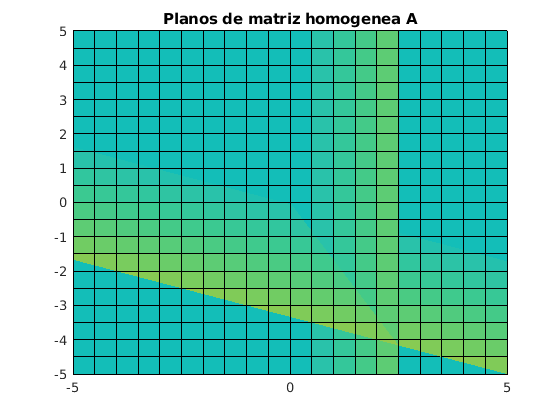


%Graficar los planos
figure
hold on;grid on; rotate3d on; 
title('Planos de matriz homogenea A')
%draw the plane: -36(x-0)+17(y-0)+10(z-4)=0
[x,y]=meshgrid(-5:0.5:8);
z11=(2.*x);
z2=(-x- 3.*y)/2;
z3=0*meshgrid(-5:0.5:8);
surf(x,y,z11);
surf(x,y,z2);
surf(x,y,z3);
xlim([-5 5]); ylim([-5 5]); zlim([-5 5]);
hold off

## SYMS

## Algebra: syms

%ecuaciones parametricas simbolicas
syms x y z
ec1=dot([x y z],[1 3 1])==0

$$ec1 = \bar{x}+3\,\bar{y}+\bar{z}=0$$

ec2=dot([x y z],[2 0 -1])==0

$$ec2 = 2\,\bar{x}-\bar{z}=0$$

ec3=dot([x y z],[1 1 0])==0

$$ec3 = \bar{x}+\bar{y}=0$$


i=[ec1;ec2;ec3];
disp(i);

$$\left(\begin{array}{c} \bar{x}+3\,\bar{y}+\bar{z}=0\\ 2\,\bar{x}-\bar{z}=0\\ \bar{x}+\bar{y}=0 \end{array}\right)$$

### Suma de ecuaciones simbolicas

disp('SUMA/RESTA:');

SUMA/RESTA:


disp('Ecuacion1+ Ecuacion2:');

Ecuacion1+ Ecuacion2:


disp(ec1+ec2);

$$3\,\bar{x}+3\,\bar{y}=0$$

disp('Ecuacion1:');

Ecuacion1:


disp(ec1);

$$\bar{x}+3\,\bar{y}+\bar{z}=0$$

disp('Ecuacion2:');

Ecuacion2:


disp(ec2);

$$2\,\bar{x}-\bar{z}=0$$

### Multiplicacion, ¿no posible DIVISION (???)

disp('MULTIPLICACION:');

MULTIPLICACION:


disp('Ecuacion1 *Ecuacion2:');

Ecuacion1 *Ecuacion2:


disp(ec1*ec2);

$$\left(2\,\bar{x}-\bar{z}\right)\,\left(\bar{x}+3\,\bar{y}+\bar{z}\right)=0$$

disp('Ecuacion1:');

Ecuacion1:


disp(ec1);

$$\bar{x}+3\,\bar{y}+\bar{z}=0$$

disp('Ecuacion2:');

Ecuacion2:


disp(ec2);

$$2\,\bar{x}-\bar{z}=0$$

disp('Multiplicacion expandida Ecuacion1 *Ecuacion2:');

Multiplicacion expandida Ecuacion1 *Ecuacion2:


disp(expand(ec1*ec2));

$$2\,{\left(\bar{x}\right)}^{2}+\bar{x}\,\bar{z}+6\,\bar{y}\,\bar{x}-{\left(\bar{z}\right)}^{2}-3\,\bar{y}\,\bar{z}=0$$

### Expansion de factores (ec1^2) elevados/potencia:.

disp('POTENCIA/expand():');

POTENCIA/expand():


disp('Ecuacion1 al cuadrado:');

Ecuacion1 al cuadrado:


disp(ec1^2);

$${\left(\bar{x}+3\,\bar{y}+\bar{z}\right)}^{2}=0$$

disp('Equacion1 al cuadrado expandida:');

Equacion1 al cuadrado expandida:


expa1=expand(ec1^2);
disp(expa1);

$${\left(\bar{x}\right)}^{2}+6\,\bar{x}\,\bar{y}+2\,\bar{x}\,\bar{z}+9\,{\left(\bar{y}\right)}^{2}+6\,\bar{y}\,\bar{z}+{\left(\bar{z}\right)}^{2}=0$$

expand(ec1*ec2): expande un factor

factor(expresion):un vector con las dos funciones vectorizadas

pretty(expresion): muestra los fraccionarios de forma bonita

## Solucion ecuaciones lineales y no lineales, y despejar ecuaciones complejas

w=x^2+2*x+9==3

$$w = x^{2}+2\,x+9=3$$

disp('Ecuacionw:');disp(w);

Ecuacionw:


$$x^{2}+2\,x+9=3$$


disp("SOLUCION ECUACION CUADRATICA:solve(v,x)")

SOLUCION ECUACION CUADRATICA:solve(v,x)


w0=solve(w,x);
pretty(w0);

/ - 1 - sqrt(5) 1i \
|                  |
\ - 1 + sqrt(5) 1i /



w01=double(w0);
disp(w01);

  -1.0000 - 2.2361i
  -1.0000 + 2.2361i



### Solucion: vpasolve(v,x)

disp("vpasolve(v,x)")

vpasolve(v,x)


t0=vpasolve(w,x);
pretty(t0);

/ - 1.0 - 2.2360679774997896964091736687313i \
|                                            |
\ - 1.0 + 2.2360679774997896964091736687313i /



w01=double(t0);
disp(t0);

$$\left(\begin{array}{c} -1.0-2.2360679774997896964091736687313\,\mathrm{i}\\ -1.0+2.2360679774997896964091736687313\,\mathrm{i} \end{array}\right)$$

## SOLUCION SISTEMA DE ECUACIONES

disp("SOLUCION ec1 ec2 ec3");

SOLUCION ec1 ec2 ec3


disp(i);

$$\left(\begin{array}{c} \bar{x}+3\,\bar{y}+\bar{z}=0\\ 2\,\bar{x}-\bar{z}=0\\ \bar{x}+\bar{y}=0 \end{array}\right)$$

[x1, y1, z1]=solve(ec1,ec2,ec3);
rta=[x1; y1; z1];
disp('Los valores de x y z de los tres planos es:');

Los valores de x y z de los tres planos es:


disp(rta);

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


disp('DESPEJE DE VARIABLES')

DESPEJE DE VARIABLES


ec1

$$ec1 = \bar{x}+3\,\bar{y}+\bar{z}=0$$

disp('x:')

x:


solve(ec1,x)

$$ans = -3\,y-z$$

disp('y:')

y:


solve(ec1,y)

$$ans = -\frac{x}{3}-\frac{z}{3}$$

disp('z:')

z:


solve(ec1,z)

$$ans = -x-3\,y$$

## Ecuaciones, DERIVADAS e INTEGRALES


disp('DERIVADA E INTEGRAL ecuacion');

DERIVADA E INTEGRAL ecuacion


syms x y z
ec= 5*x^3- 3*x^2 + 2*x -10

$$ec = 5\,x^{3}-3\,x^{2}+2\,x-10$$

derivada=diff(ec,x);
integral=int(derivada,x);
disp('Derivada:');

Derivada:


disp(derivada);

$$15\,x^{2}-6\,x+2$$

disp('Integral: ')

Integral: 


disp(integral)

$$x\,\left(5\,x^{2}-3\,x+2\right)$$

inte_Expa=expand(integral);
disp('Integral Expandida: ')

Integral Expandida: 


disp(inte_Expa)

$$5\,x^{3}-3\,x^{2}+2\,x$$


disp('INTEGRALES CON LIMITES: ')

INTEGRALES CON LIMITES: 


inte_lims=int(ec,x,0.1,0.2);
disp(integral)

$$x\,\left(5\,x^{2}-3\,x+2\right)$$

## Grafica de planos de manera simbolica

syms x y z
%ecuaciones parametricas simbolicas
ec1=dot([x y z],[1 3 1])==0

$$ec1 = \bar{x}+3\,\bar{y}+\bar{z}=0$$

ec2=dot([x y z],[2 0 -1])==0

$$ec2 = 2\,\bar{x}-\bar{z}=0$$

ec3=dot([x y z],[1 1 0])==0

$$ec3 = \bar{x}+\bar{y}=0$$

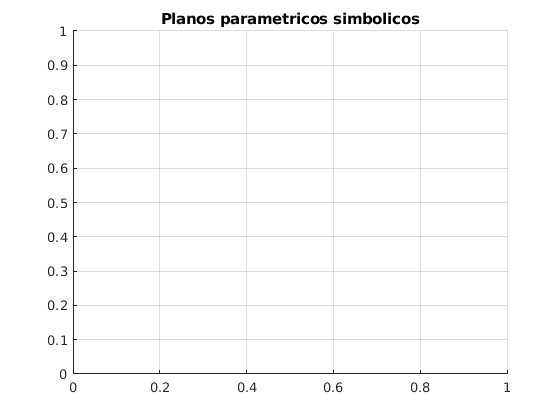


a=solve(ec1,z);
b=solve(ec2,z);
c=solve(ec3,z);


%Graficar los planos
figure
hold on;grid on; rotate3d on; 
title('Planos parametricos simbolicos')


[x,y]=meshgrid(-5:0.5:8);
surf(x,y,a);

Error using surf (line 71)
Z must be a matrix, not a scalar or vector.

surf(x,y,b);
surf(x,y,c);
xlim([-5 5]); ylim([-5 5]); zlim([-5 5]);
hold off